## Polar Overturning Conceptual Model

#### Live script to run experiments in paper and produce the figures.

#### twnh Aug, Sep '19, Jan–May '20

Housekeeping:

clear
close all
%parpool('MJSProfile1',84) 
if(isempty(gcp))
    %parpool('MJSProfile1',84) 
    
    parpool('local',16) 
end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.


Define universal parameters:

[geophysical_parameters, static_parameters] = define_POC_static_parameters ;
plot_options = define_POC_plot_options ;

Exp 1: Northern hemisphere Fram Strait/Barents Sea Opening.

[this_case,dynamic_parameters] = define_POC_case('NH_FSBSO_can',static_parameters,geophysical_parameters) ;
[sens,vals] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;

ff = [1], these inds = [1 : 1]. 

theory = compute_POC_theory(dynamic_parameters,static_parameters,geophysical_parameters) ;
model1 = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens,'vals',vals,'theory',theory) ;
report_POC_results(model1)
plot_POC_solution(model1)

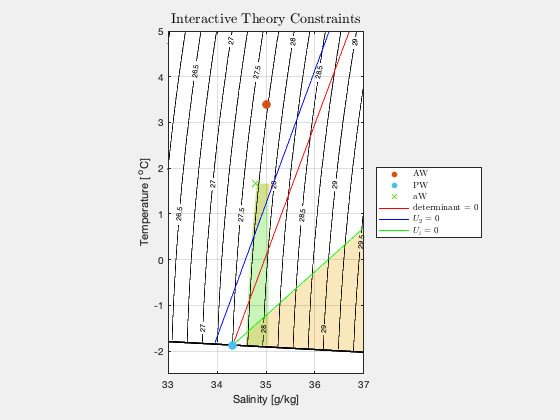

plot_POC_interactive_TS_diagram(model1)

Exp 2: Modified Northern hemisphere Fram Strait/Barents Sea Opening (higher Q).

[this_case,dynamic_parameters] = define_POC_case('NH_FSBSO_mod',static_parameters,geophysical_parameters) ;
[sens,vals] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;
theory = compute_POC_theory(dynamic_parameters,static_parameters,geophysical_parameters) ;
model2 = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens,'vals',vals,'theory',theory) ;
report_POC_results(model2)
plot_POC_solution(model2)

Exp X: Modified Northern hemisphere Fram Strait/Barents Sea Opening (intermediate Q).

[this_case,dynamic_parameters] = define_POC_case('NH_FSBSO_int',static_parameters,geophysical_parameters) ;
[sens,vals] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;
theory = compute_POC_theory(dynamic_parameters,static_parameters,geophysical_parameters) ;
modelX = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens,'vals',vals,'theory',theory) ;
report_POC_results(modelX)
plot_POC_solution(modelX)

Make figure showing entrainment/shelf circulation tradeoff

plot_POC_tradeoff(model1,model2)

Exp 3: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values.

[this_case,dynamic_parameters] = define_POC_case('NH_FSBSO_range',static_parameters,geophysical_parameters) ;
[sens,~] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;
model3 = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens) ;
report_POC_results(model3)
plot_POC_solutions1(model3,model1,model2)

Exp 4: Northern hemisphere Fram Strait/Barents Sea Opening with wide range of all parameters.

[this_case,dynamic_parameters] = define_POC_case('NH_FSBSO_sens',static_parameters,geophysical_parameters) ;
[sens,~] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;
model4 = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens) ;
report_POC_results(model4)
plot_POC_solutions2(model4,model3)

Exp 5: Northern hemisphere Fram Strait/Barents Sea Opening with various S_2 values.

[this_case,dynamic_parameters] = define_POC_case('NH_FSBSO_S2_range',static_parameters,geophysical_parameters) ;
[sens,~] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;
model5 = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens) ;
report_POC_results(model5)
plot_POC_solution3(model5,model1)

DEBUG! Exp Y: Modified Northern hemisphere Fram Strait/Barents Sea Opening (small S2).

[this_case,dynamic_parameters] = define_POC_case('NH_FSBSO_small_S2',static_parameters,geophysical_parameters) ;
[sens,vals] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;
theory = compute_POC_theory(dynamic_parameters,static_parameters,geophysical_parameters) ;
modelY = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens,'vals',vals,'theory',theory) ;
report_POC_results(modelY)
plot_POC_solution(modelY)

Compare numerical results to theory

plot_POC_solutions_and_theory(model4)

Exp 6: Southern hemisphere.

[this_case,dynamic_parameters] = define_POC_case('SH_can',static_parameters,geophysical_parameters) ;
[sens,vals] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;
theory = compute_POC_theory(dynamic_parameters,static_parameters,geophysical_parameters) ;
model6 = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens,'vals',vals,'theory',theory) ;
report_POC_results(model6)
plot_POC_solution(model6)

Exp 7: Southern hemisphere with many Q values

[this_case,dynamic_parameters] = define_POC_case('SH_range',static_parameters,geophysical_parameters) ;
[sens,~] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;
model7 = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens) ;
report_POC_results(model7)
plot_POC_solutions1(model7,model6,model6)
return

Exp 8: Southern hemisphere Antarctic as a whole

[this_case,dynamic_parameters] = define_POC_case('SH_sens',static_parameters,geophysical_parameters) ;
[sens,~] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;
model8 = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens) ;
report_POC_results(model8)
plot_POC_solutions2(model8,model7)
plot_POC_solutions_and_theory(model8)